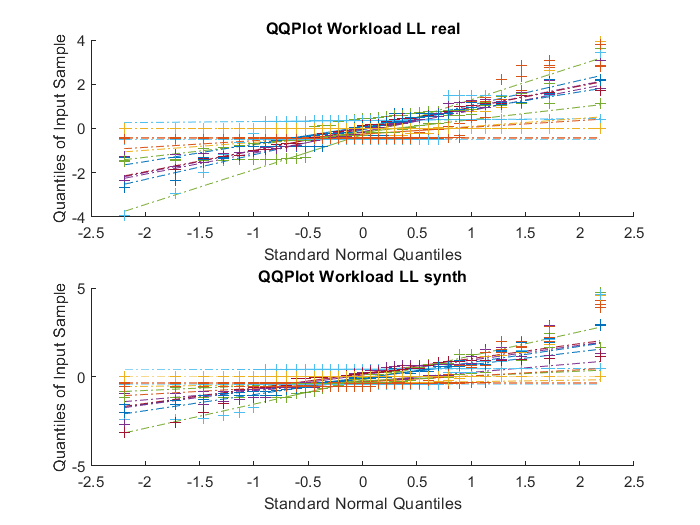

clear all; 
close all; 
clc;

%% Read the data
% real=xlsread("WL_Caratterizzati\WL_LL_12cluster.xlsx");
%synthetic=xlsread("WL_Caratterizzati\WL_LL1_12cluster_buono2.xlsx");

real = xlsread("workload_lowlevel_LL_char.xlsx");
synthetic=xlsread("workload_lowlevel1_LL1_char.xlsx");

real = zscore(real);
synthetic = zscore(synthetic);


%data can have different rows, but the same columns (components)
N=size(real,2); %number of columns
real=real(:, 1:N-1); %remove clustering column
synthetic = synthetic(:, 1:N-1); %remove clustering column

%% Normal Distribution - One-sample Kolmogorov-Smirnov test
[h_ks_real,p_ks_real] = kstest(real);
[h_ks_synth,p_ks_synth] = kstest(synthetic);

%% Normal Distribution - Visual Test
figure();
subplot(2,1,1);
qqplot(real);
title('QQPlot Workload LL real')
subplot(2,1,2);
qqplot(synthetic);
title('QQPlot Workload LL synth')

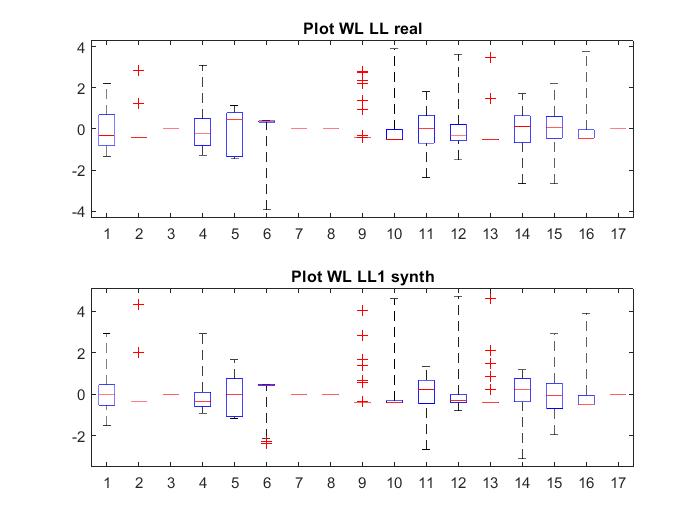



%% Equal Variance - Two sample F-test for equal variances
[h_var, p_var] = vartest2(synthetic,real);

%% Equal Variance
figure();
subplot(2,1,1);
boxplot(real, 'Whisker', 100);
title('Plot WL LL real')
subplot(2,1,2);
boxplot(synthetic, 'Whisker', 100);
title('Plot WL LL1 synth')


%% Two sample T-test
[h_ttset, p_ttest] = ttest2(synthetic,real);

%% Two sample T-test without Assuming Equal Variances
[h_ttset_novar, p_ttest_novar] = ttest2(synthetic,real, 'Vartype', 'unequal');

%% Non parametric Test - Wilcoxon Test
p_wilc = zeros(1,N-1);
h_wilc = zeros(1,N-1);
for i= 1:N-1
    [p_wilc(i), h_wilc(i)] = ranksum(synthetic(:,i), real(:,i));
end